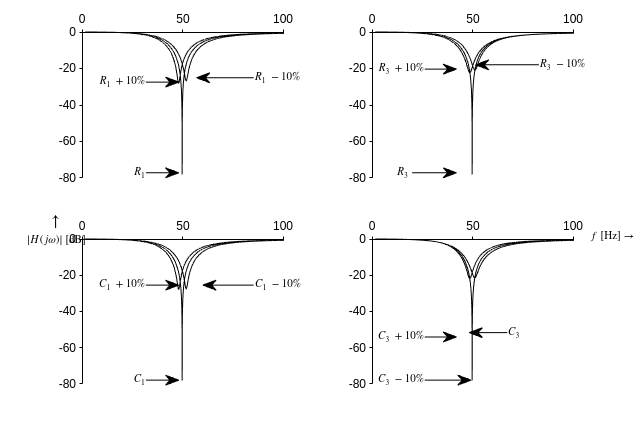

close all
clear
cd('/home/frederik/Documents/');

% Transfer function
alpha = 0.85;
omega = logspace(1,2.8,10000);
f = omega/(2*pi);
s = tf('s');

% Base values
R1 = 68e3 * 2;
R2 = 68e3;
C1 = 47e-9 / 2;
C2 = 47e-9;

% Generate transfer functions
H = cell(9,1);
H{1} = transfer_function(R1, R1, R2, C1, C1, C2, alpha, omega); % Nominal
H{2} = transfer_function(R1 * 1.1, R1, R2, C1, C1, C2, alpha, omega);
H{3} = transfer_function(R1 * 0.9, R1, R2, C1, C1, C2, alpha, omega);
H{4} = transfer_function(R1, R1, R2 * 1.1, C1, C1, C2, alpha, omega);
H{5} = transfer_function(R1, R1, R2 * 0.9, C1, C1, C2, alpha, omega);
H{6} = transfer_function(R1, R1, R2, C1 * 1.1, C1, C2, alpha, omega);
H{7} = transfer_function(R1, R1, R2, C1 * 0.9, C1, C2, alpha, omega);
H{8} = transfer_function(R1, R1, R2, C1, C1, C2 * 1.1, alpha, omega);
H{9} = transfer_function(R1, R1, R2, C1, C1, C2 * 0.9, alpha, omega);

% Define figure size
fig_width = 6.6;  
fig_height = 4.5; 
figure;
set(gcf, 'Units', 'Inches', 'Position', [1, 1, fig_width, fig_height]);

% Create tiled layout
t = tiledlayout(2,2);
t.Padding = 'loose';  
t.TileSpacing = 'loose';

% Define plot groups
plot_groups = {
    [1, 2, 3], 'Resistor Sensitivity';
    [1, 4, 5], 'Resistor Sensitivity';
    [1, 6, 7], 'Capacitor Sensitivity';
    [1, 8, 9], 'Capacitor Sensitivity';
};

% Plot function
for i = 1:4
    ax = nexttile;
    hold on
    for idx = plot_groups{i,1}
        plot(f, mag2db(abs(H{idx})), 'Color', 'Black');
    end
    hold off
    format_plot(ax);
end


text(108,2,'$f \: [\mbox{Hz}] \rightarrow$', 'Interpreter', 'latex', 'FontSize', 8);
text(108,170,'$f \: [\mbox{Hz}] \rightarrow$', 'Interpreter', 'latex', 'FontSize', 8);
text(-172,165,'$|H(j\omega)| \: [\mbox{dB}]$', 'Interpreter', 'latex', 'FontSize', 8);
text(-160,175,'$\uparrow$', 'Interpreter', 'latex', 'FontSize', 12);
text(-172,0,'$|H(j\omega)| \: [\mbox{dB}]$', 'Interpreter', 'latex', 'FontSize', 8);
text(-160,10,'$\uparrow$', 'Interpreter', 'latex', 'FontSize', 12);

annotation('textarrow', [0.23, 0.282], [0.81, 0.81], 'String', '$R_1 \: +10\%$', 'Interpreter','latex', 'FontSize', 8);
annotation('textarrow', [0.23, 0.282], [0.60, 0.60], 'String', '$R_1$', 'Interpreter','latex', 'FontSize', 8);
annotation('textarrow', [0.4, 0.31], [0.82, 0.82], 'String', '$R_1 \: - 10\%$', 'Interpreter','latex', 'FontSize', 8);

annotation('textarrow', [0.23, 0.282], [0.34, 0.34], 'String', '$C_1 \: +10\%$', 'Interpreter','latex', 'FontSize', 8);
annotation('textarrow', [0.23, 0.282], [0.12, 0.12], 'String', '$C_1$', 'Interpreter','latex', 'FontSize', 8);
annotation('textarrow', [0.4, 0.32], [0.34, 0.34], 'String', '$C_1 \: - 10\%$', 'Interpreter','latex', 'FontSize', 8);

annotation('textarrow', [0.67, 0.72], [0.84, 0.84], 'String', '$R_3 \: +10\%$', 'Interpreter','latex', 'FontSize', 8);
annotation('textarrow', [0.65, 0.72], [0.6, 0.6], 'String', '$R_3 \:$', 'Interpreter','latex', 'FontSize', 8);
annotation('textarrow', [0.85, 0.75], [0.85, 0.85], 'String', '$R_3 \: -10\% \:$', 'Interpreter','latex', 'FontSize', 8);

annotation('textarrow', [0.67, 0.72], [0.22, 0.22], 'String', '$C_3 \: +10\%$', 'Interpreter','latex', 'FontSize', 8);
annotation('textarrow', [0.80, 0.74], [0.23, 0.23], 'String', '$C_3 \: $', 'Interpreter','latex', 'FontSize', 8);
annotation('textarrow', [0.67, 0.743], [0.12, 0.12], 'String', '$C_3 \: -10\%$', 'Interpreter','latex', 'FontSize', 8);
saveas(gcf, 'notch_component_sensitivity.pdf');

%Pole zero plots
H1 = transfer_function2(68e3*2,68e3*2,68e3,47e-9/2,47e-9/2,47e-9,alpha,s);
H2 = transfer_function2(68e3*2,68e3*2,68e3*1.1,47e-9/2,47e-9/2,47e-9,alpha,s);
H3 = transfer_function2(68e3*2,68e3*2,68e3*0.9,47e-9/2,47e-9/2,47e-9,alpha,s);
fig_width = 6.6;  % in inches
fig_height = 4; % in inches
figure;
set(gcf, 'Units', 'Inches', 'Position', [1, 1, fig_width, fig_height]);
pzmap(H1,'k',H2,'r',H3,'b')
box off;
title('Pole-zero map with $R_3$ varying from nominal value','Interpreter','latex')
%legend({'$R_3$','$R_3 + 10\%$','$R_3 - 10\%$'},'Interpreter','latex','Location','southwest');
saveas(gcf, 'notch_component_polezero.pdf');

function [H] = transfer_function(R1,R2,R3,C1,C2,C3,alpha,omega)
    H = (-1i*C1*C2*C3*R1*R2*R3.*omega.^3 - C1*C2*R1*R3.*omega.^2 - C1*C2*R2*R3.*omega.^2 ...
     + 1i*C1*R3.*omega + 1i*C2*R3.*omega + 1) ./ ...
    (1i*C2*R3.*omega + C1*C3*R1*R3*alpha.*omega.^2 + C2*C3*R1*R2*alpha.*omega.^2 ...
     + C2*C3*R1*R3*alpha.*omega.^2 - C1*C2*R1*R3.*omega.^2 - C1*C2*R2*R3.*omega.^2 ...
     - C1*C3*R1*R3.*omega.^2 - C2*C3*R1*R2.*omega.^2 - C2*C3*R1*R3.*omega.^2 ...
     - 1i*C1*C2*C3*R1*R2*R3.*omega.^3 + 1i*C1*R3.*omega - 1i*C2*R2*alpha.*omega ...
     + 1i*C3*R1.*omega + 1i*C2*R2.*omega - 1i*C2*R1*alpha.*omega + 1i*C2*R1.*omega ...
     - 1i*C3*R1*alpha.*omega + 1);
end

function [H] = transfer_function2(R1,R2,R3,C1,C2,C3,alpha,s)
    H = (C1*C2*C3*R1*R2*R3*s^3+C1*C2*R1*R3*s^2+C1*C2*R2*R3*s^2+C1*R3*s+C2*R3*s+1)/(C1*C2*C3*R1*R2*R3*s^3-C1*C3*R1*R3*alpha*s^2-C2*C3*R1*R2*alpha*s^2-C2*C3*R1*R3*alpha*s^2+C1*C2*R1*R3*s^2+C1*C2*R2*R3*s^2+C1*C3*R1*R3*s^2+C2*C3*R1*R2*s^2+C2*C3*R1*R3*s^2-C2*R1*alpha*s-C2*R2*alpha*s-C3*R1*alpha*s+C1*R3*s+C2*R1*s+C2*R2*s+C2*R3*s+C3*R1*s+1)
end

% Function to format plots
function format_plot(ax)
    ax.XAxisLocation = 'origin';
    ax.YAxisLocation = 'origin';
    set(ax, 'Box', 'off', 'TickDir', 'out', 'XColor', 'k', 'YColor', 'k');
end